# Bifurcation diagram with quintic nonlinearity

Modifies the example `continuationInstructions.mlx` to include a quintic nonlinearity instead of a cubic term.

## Construct the quantum graph and find the first few eigenfunctions

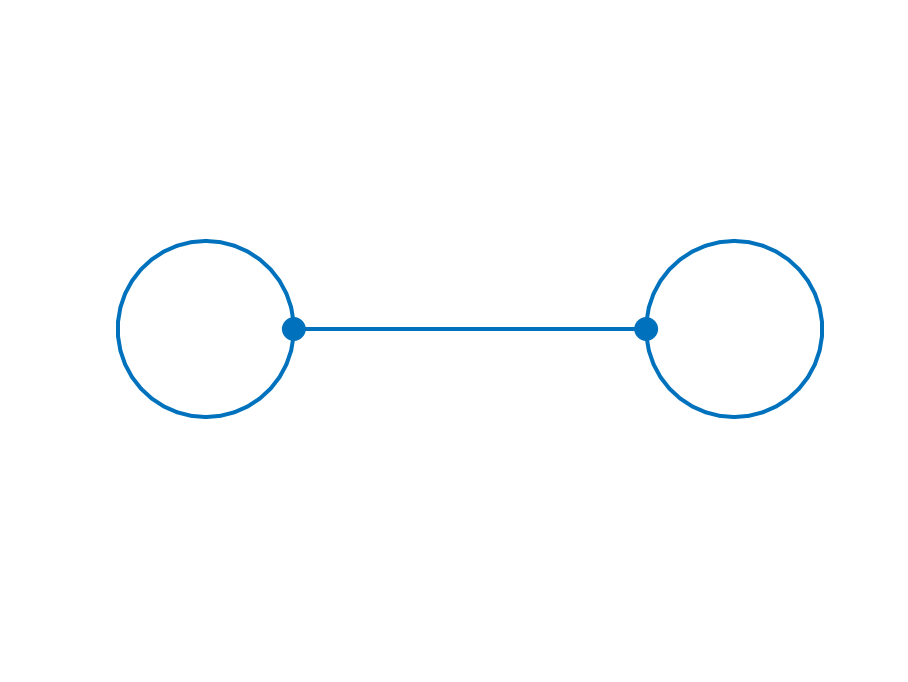

Created directory data/dumbbell/131.
Run number is 131.


tag='dumbbell';
L = [2*pi 4 2*pi];
nxvec=6;
Phi=quantumGraphFromTemplate(tag,'LVec',L,'nX',nxvec,'discretization','Uniform');
dataDir = makeContinuationDirectory(Phi,tag);

#### Compute and save some eigenfunctions

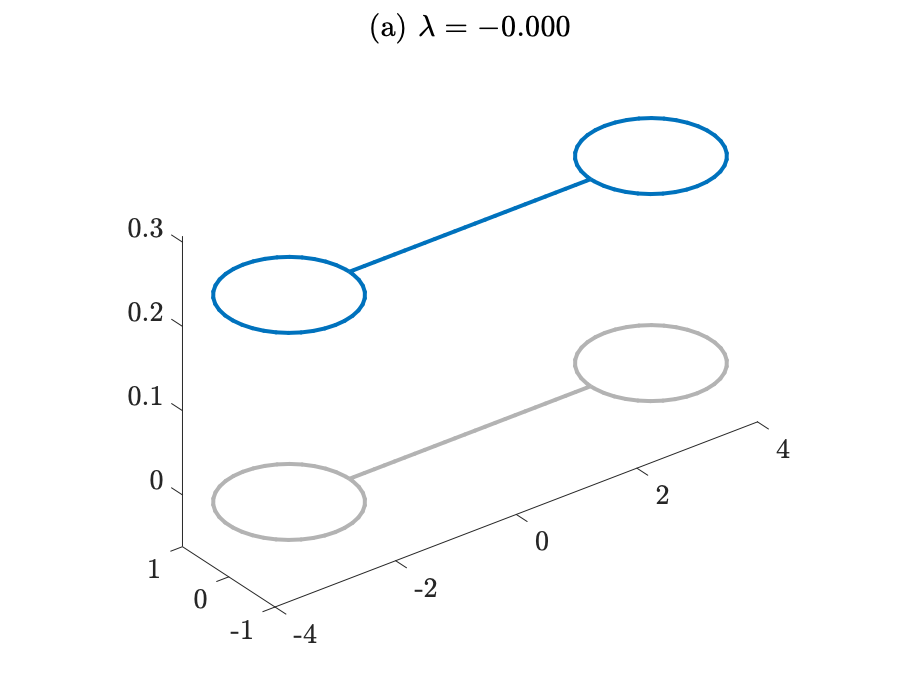

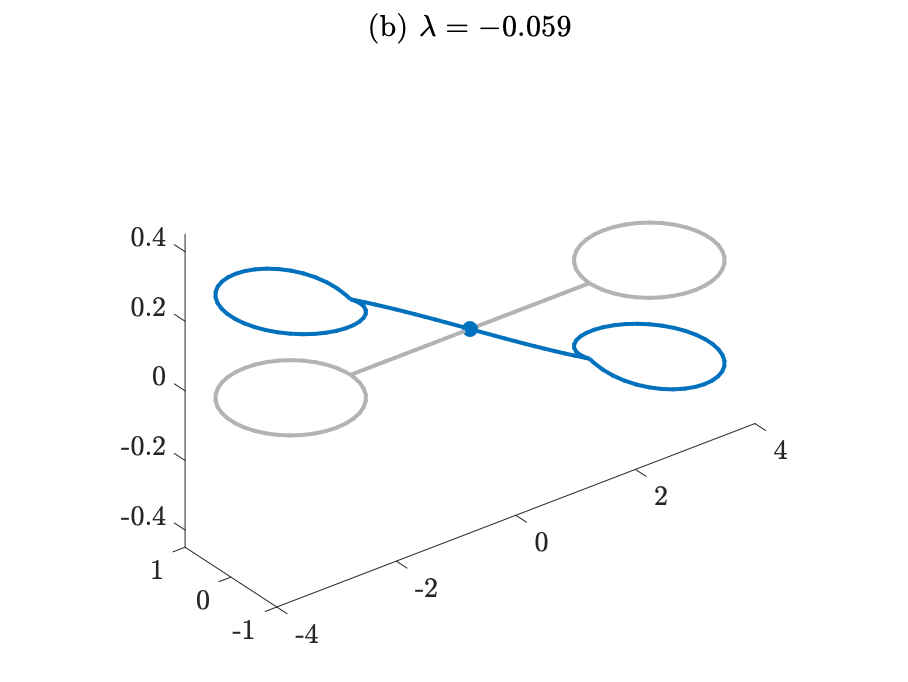

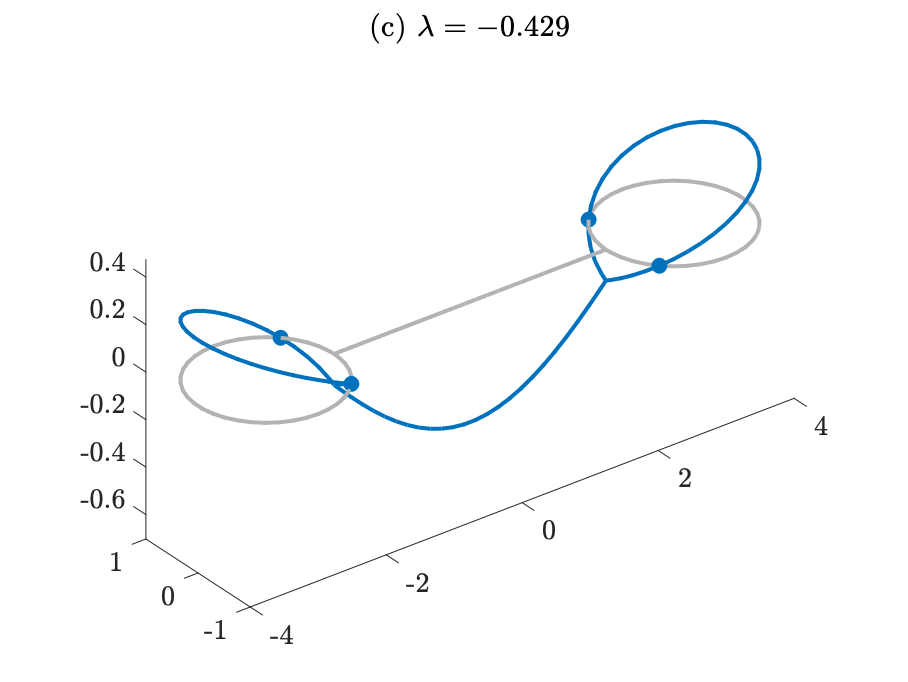

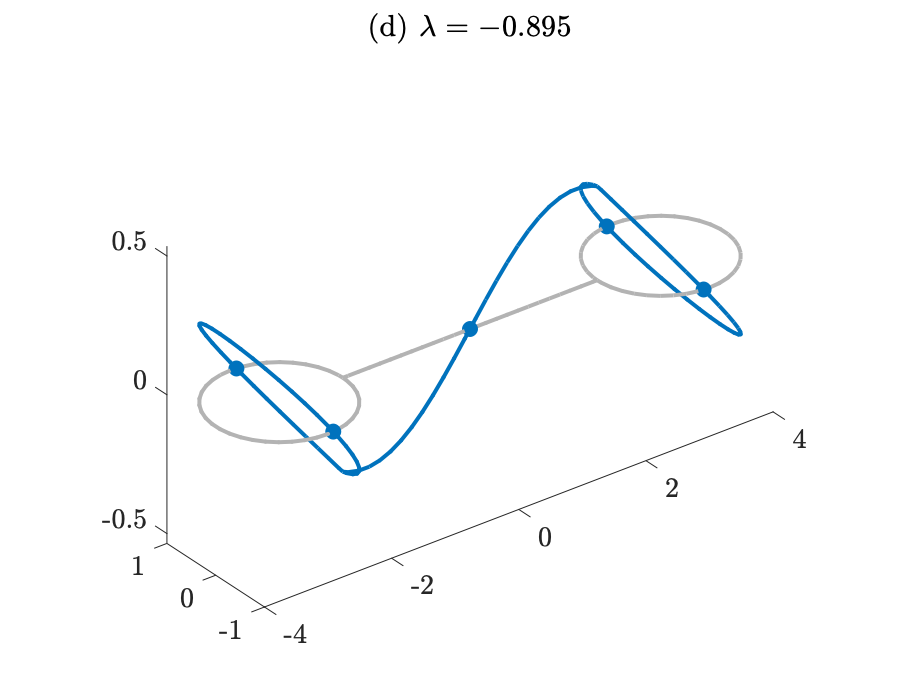

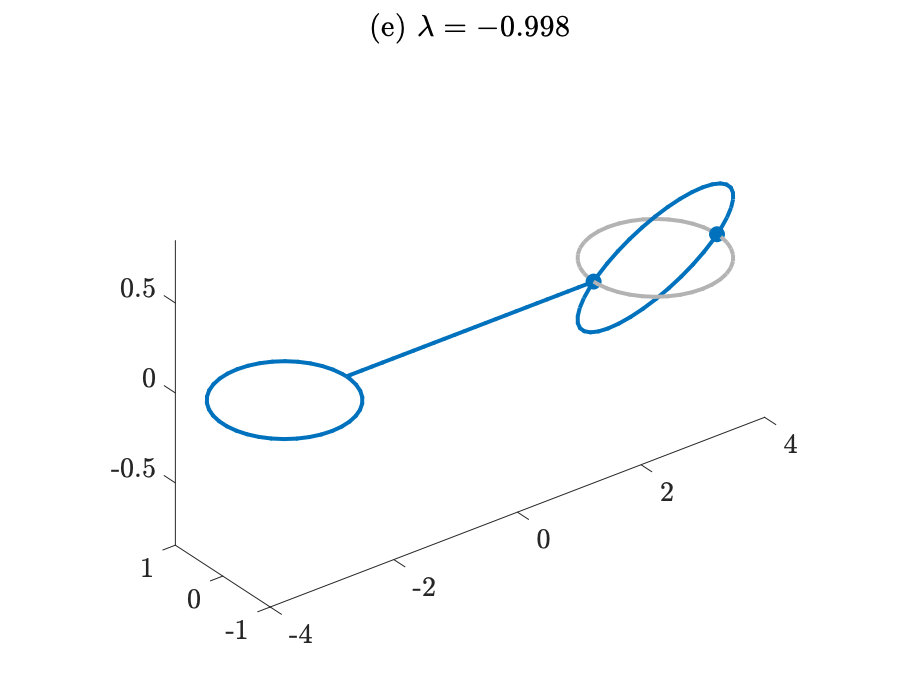

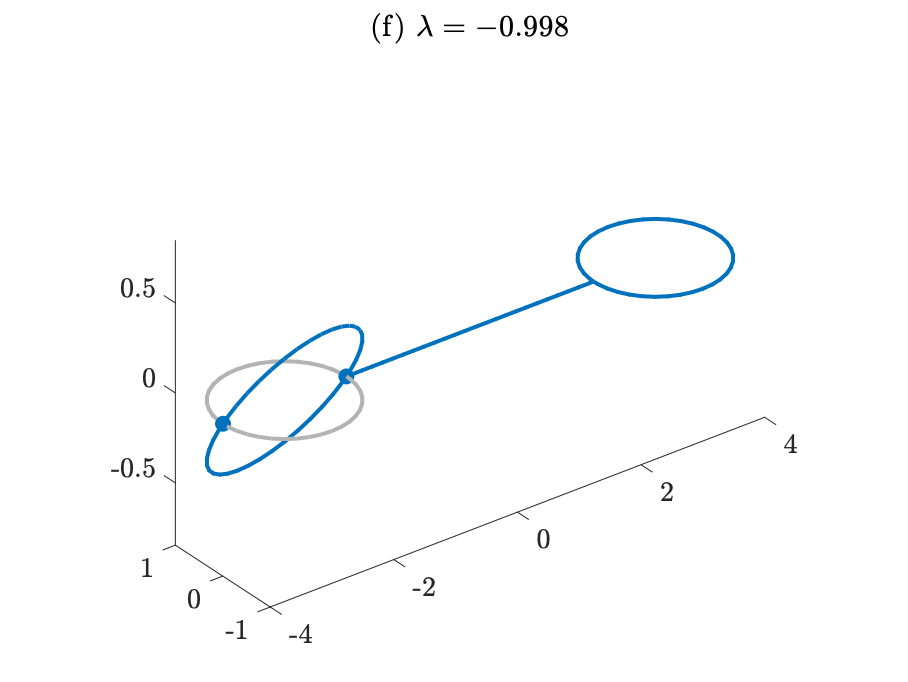

nToPlot=4;
nDoubles=1;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

#### Define the quintic nonlinearity and save it to the data directory. 

This must be a symbolic function of a single variable `z`. The default is $f(z)= 2z^3$, but we change this here to $f(z)= 3 z^5$. 

syms z
f = 3*z^5;
fcns = saveNLSFunctionsGraph(dataDir,Phi,f);

## Compute branches that are continuation of the three least oscillatory eigenfunctions

- The function `continuerSet` acts like the MATLAB functions `odeset` and `optimset.` It sets a number of options that are used by the continuation programs

- The function `continueFromEig` continues a branch from the linear limit of an eigenfunction computed in the previous step

options=continuerSet([],'maxTheta',1,'LambdaThresh',-1,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);
branch1=continueFromEig(dataDir,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/dumbbell/131/branch001.
Branching Bifurcation at solution number 5.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 15.
Branching Bifurcation at solution number 20.
Branching Bifurcation at solution number 29.
Branching Bifurcation at solution number 38.


options=continuerSet(options,'maxTheta',2);
branch2=continueFromEig(dataDir,2,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data/dumbbell/131/branch002.
No branching bifurcations found.


branch3=continueFromEig(dataDir,3,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data/dumbbell/131/branch003.
No branching bifurcations found.


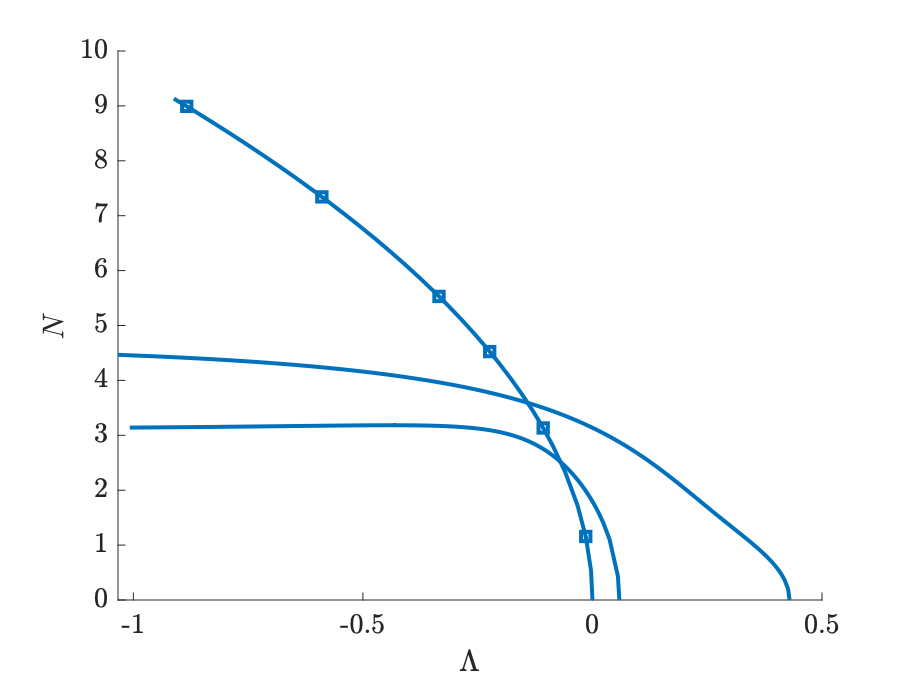

bifurcationDiagram(dataDir)

## Compute some branches that bifurcate from this first branch

- The function `continueFromBranchpoint` continues a branch from the first branching bifurcation point. Since this is a symmetry-breaking bfirucation, we only need to continue in one direction, the branch stored in branch`1` at bifurcation location 1 

location=1;
direction=1;
branch4=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data/dumbbell/131/branch004.
No branching bifurcations found.


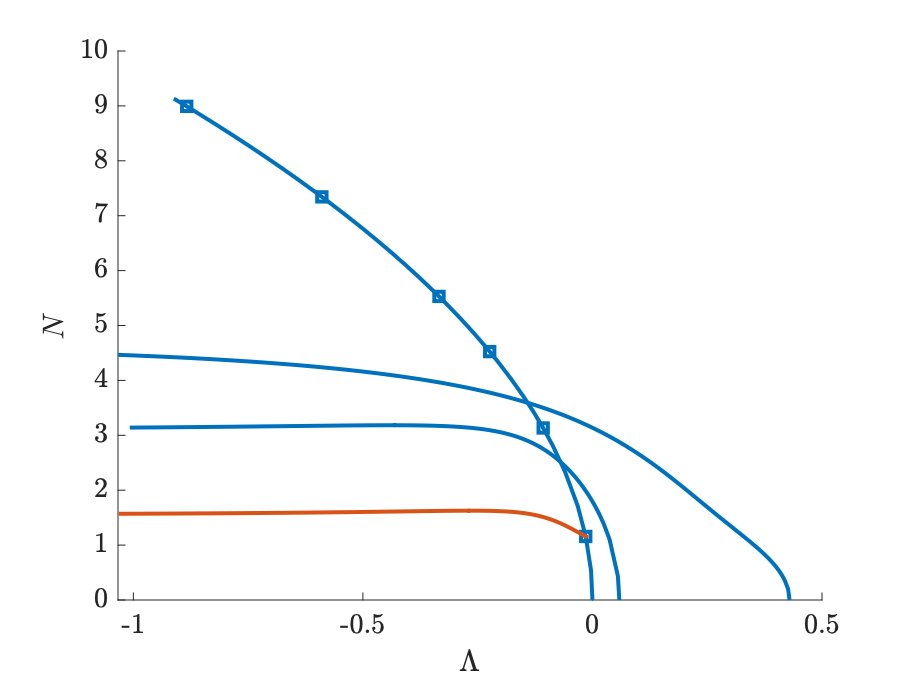

bifurcationDiagram(dataDir)

location=2;
direction=1;
branch5=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 5.
Data saved to directory data/dumbbell/131/branch005.
Branching Bifurcation at solution number 28.


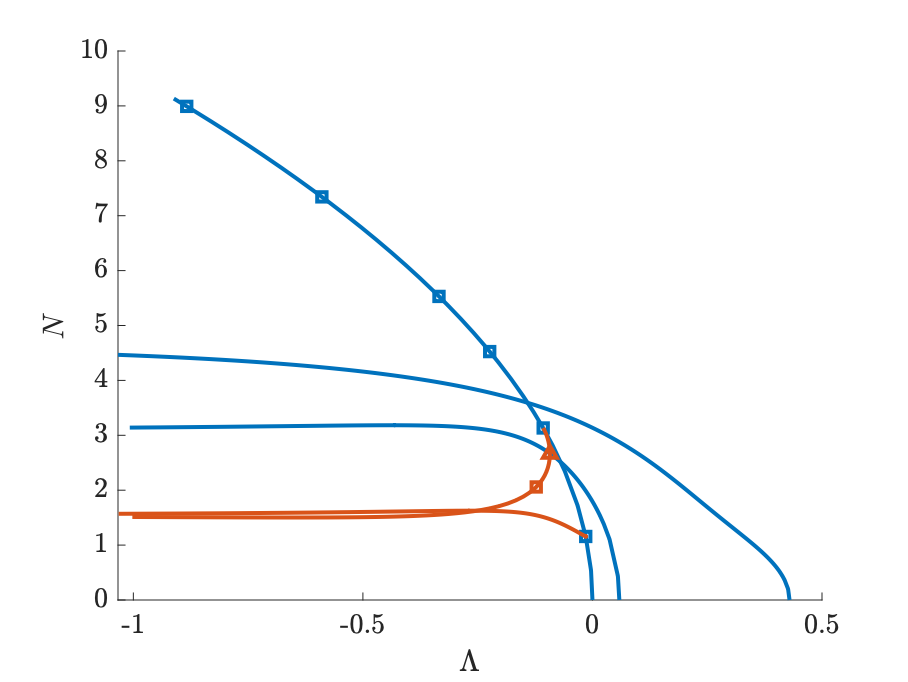

bifurcationDiagram(dataDir)

location=2;
direction=-1;
branch6=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 6.
Data saved to directory data/dumbbell/131/branch006.
No branching bifurcations found.


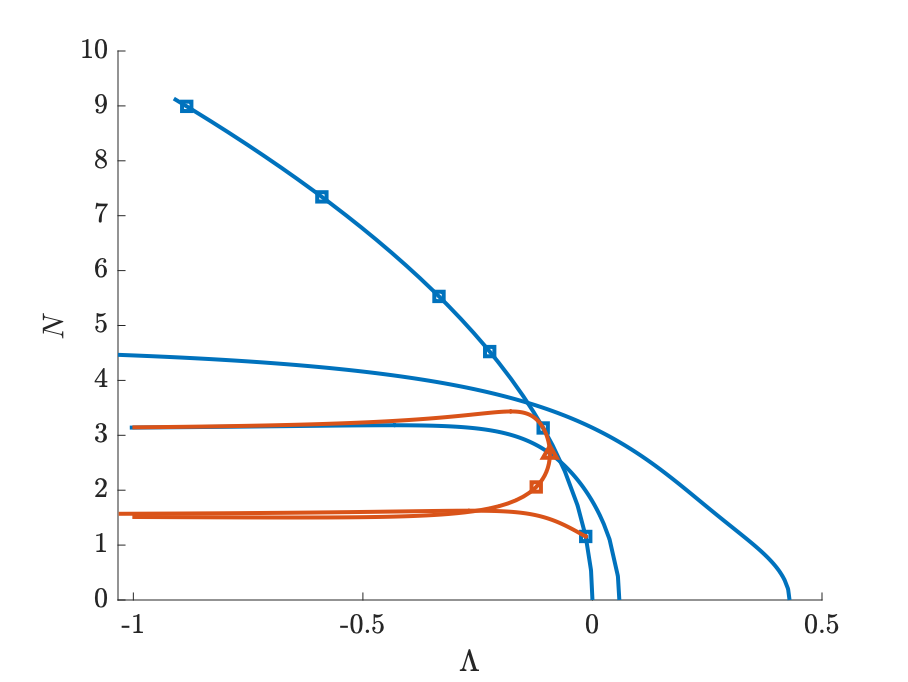

bifurcationDiagram(dataDir)

location=3;
direction=1;
branch7=continueFromBranchPoint(dataDir,branch1,location,direction,options);

Lambda threshold crossed.
Branch number 7.
Data saved to directory data/dumbbell/131/branch007.
No branching bifurcations found.


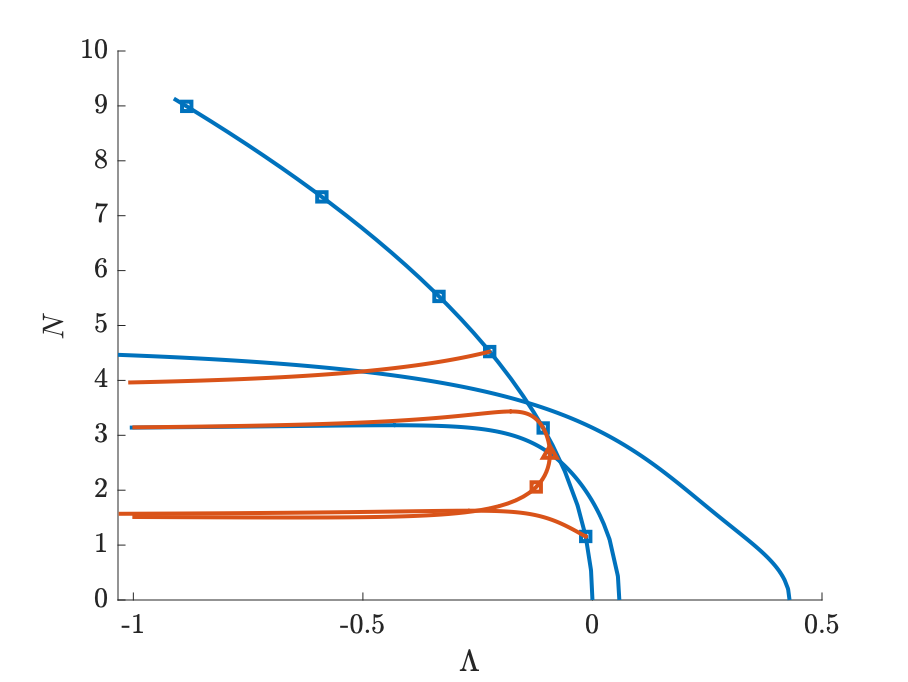

bifurcationDiagram(dataDir)